clear
clc
close all

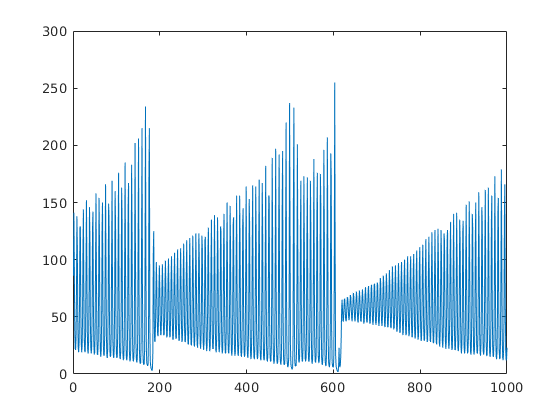

data_train = readtable("lasertrain.dat");
data_train(:,1:3) = [];
data_train = table2array(data_train);

figure
plot(data_train)

## Standardize Data

For a better fit and to prevent the training from diverging, standardize the training data to have zero mean and unit variance. At prediction time, you must standardize the test data using the same parameters as the training data.

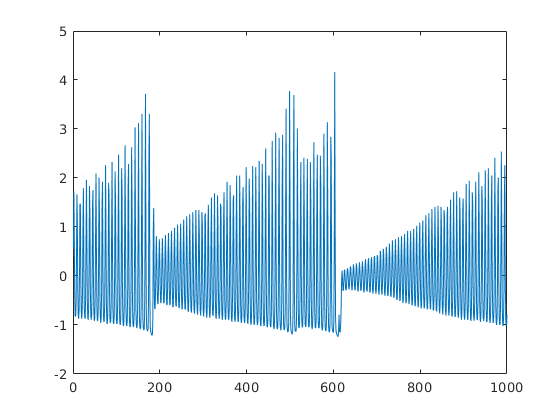

mu = mean(data_train);
sig = std(data_train);

data_train_standardised = (data_train - mu) / sig;
num_timesteps_train = numel(data_train_standardised);
plot(data_train_standardised)

## Prepare Predictors and Responses

% Getting target and training data with lag
lag = 30;
[x_train_temp, y_train] = getTimeSeriesTrainData(data_train_standardised, lag);

% Formatting training data for trainNetwork function
x_train = cell(1000-lag,1);

for i=1:(1000-lag)
    x_train{i,1} = x_train_temp(:,i)';
end

y_train = y_train';

## **Define LSTM Network Architecture**

Create an LSTM regression network. Specify the LSTM layer to have 200 hidden units.

num_features = 1;
num_responses = 1;
num_hidden_units = 200;

layers = [ ...
    sequenceInputLayer(num_features)
    lstmLayer(num_hidden_units, 'OutputMode','last')
    fullyConnectedLayer(num_responses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',300, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',150, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

## Train LSTM Network

Train the LSTM network with the specified training options by using `trainNetwork`.

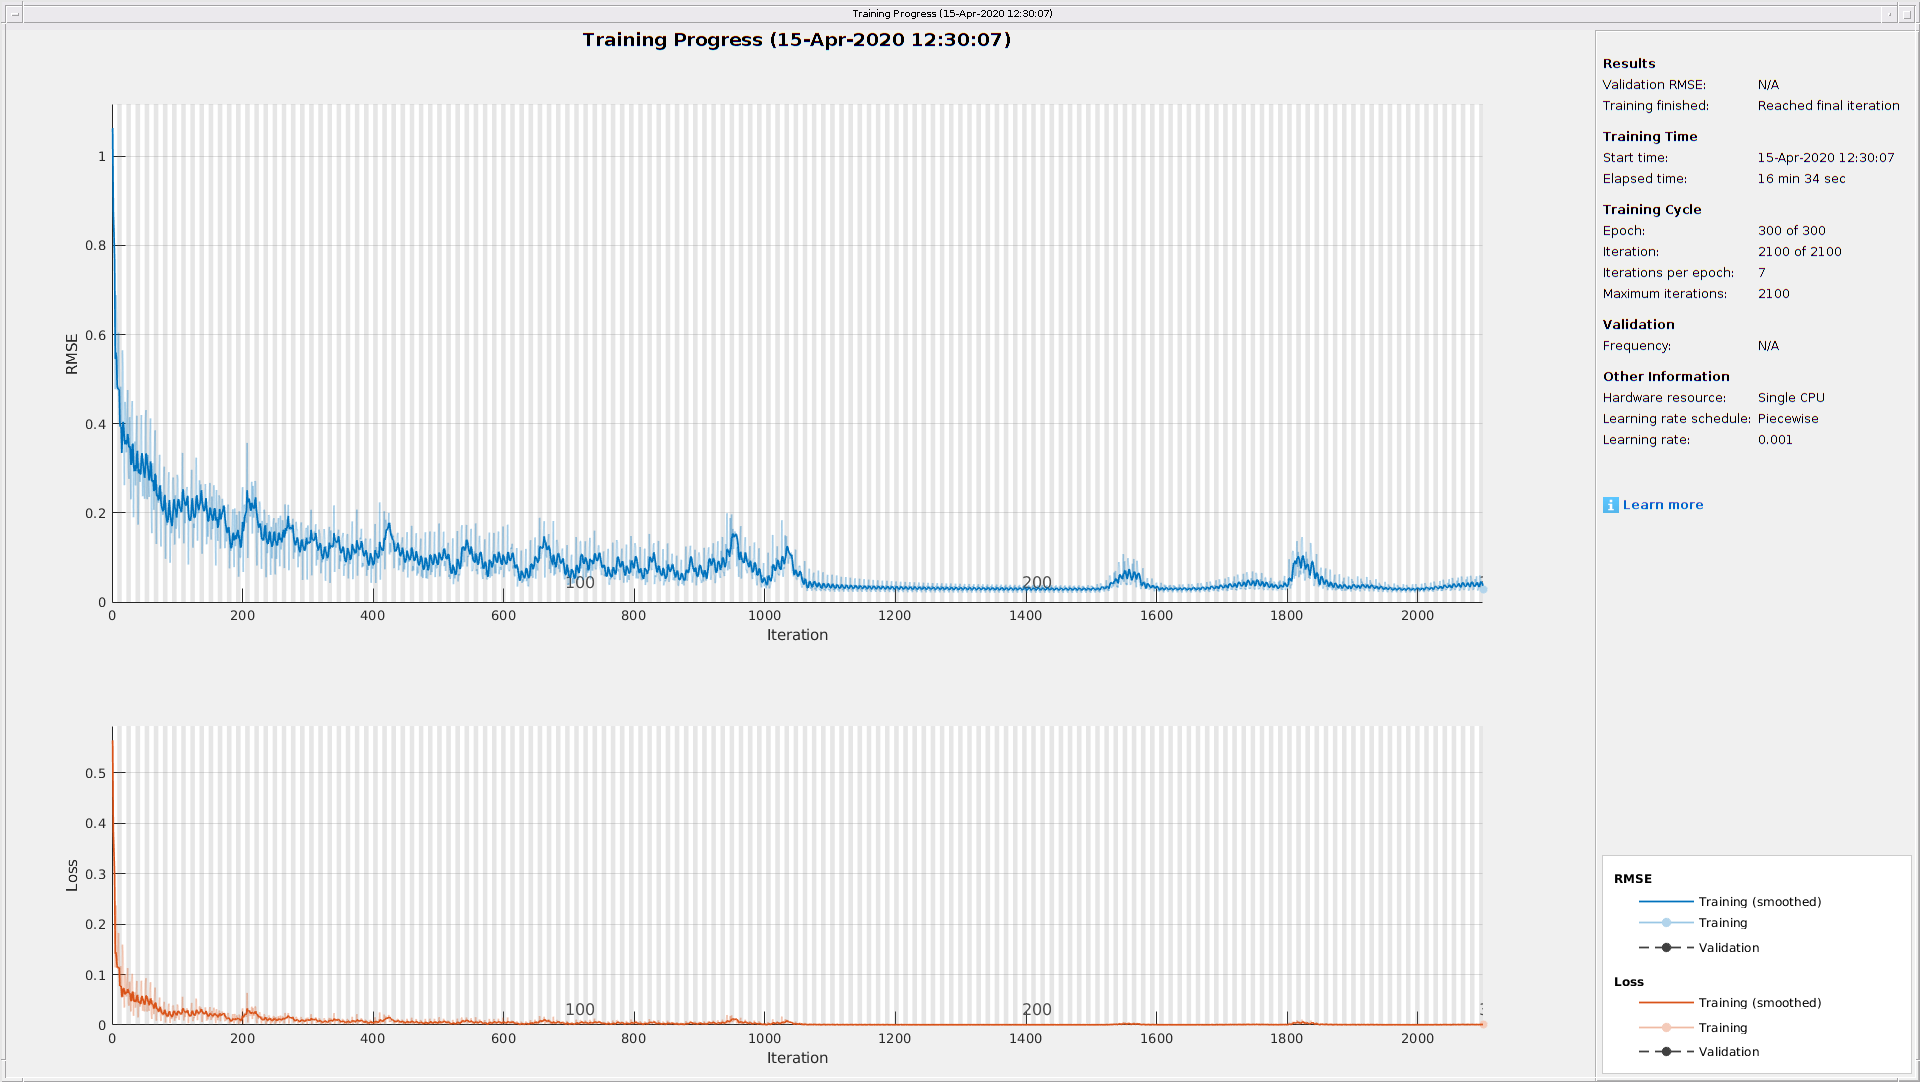

net = trainNetwork(x_train,y_train,layers,options);

## Forecast Future Time Steps

To forecast the values of multiple time steps in the future, use the `predictAndUpdateState` function to predict time steps one at a time and update the network state at each prediction. For each prediction, use the previous prediction as input to the function.

Standardize the test data using the same parameters as the training data.

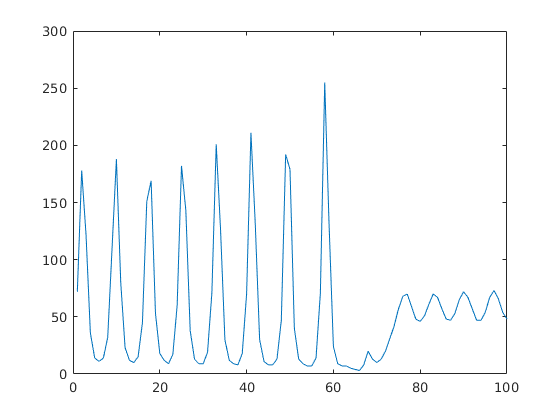

data_test = readtable("laserpred.dat");
data_test(:,1:3) = [];
data_test = table2array(data_test);
num_timesteps_test = numel(data_test);

figure
plot(data_test)

data_test_standardised = (data_test - mu) / sig;

To initialize the network state, first predict on the training data `XTrain`. Next, make the first prediction using the last time step of the training response `YTrain(end)`. Loop over the remaining predictions and input the previous prediction to `predictAndUpdateState`.

%net = predictAndUpdateState(net,x_train);

For large collections of data, long sequences, or large networks, predictions on the GPU are usually faster to compute than predictions on the CPU. Otherwise, predictions on the CPU are usually faster to compute. For single time step predictions, use the CPU. To use the CPU for prediction, set the `'ExecutionEnvironment'` option of `predictAndUpdateState` to `'cpu'`.

testing_input = y_train((end-lag+1):end,:);
predictions = zeros(1, numel(data_test_standardised));
num_timesteps_test = numel(data_test);

for i=1:num_timesteps_test
    [net, y] = predictAndUpdateState(net,testing_input');
    testing_input = vertcat(testing_input(2:end),y);
    predictions(1,i) = y;
end

Error using DAGNetwork/predictRNN>iAssertInitialStateIsValidForPredict (line 69)
Incorrect network state. The network expects mini-batches size of 74, but was passed a mini-batch of size 1.

Error in DAGNetwork/predictRNN (line 11)
iAssertInitialStateIsValidForPredict(statefulLayers, dispatcher.MiniBatchSize)

Error in 

y_pred = sig*predictions + mu;

The training progress plot reports the root-mean-square error (RMSE) calculated from the standardized data. Calculate the RMSE from the unstandardized predictions.

y_test = data_test;
rmse = sqrt(mean((y_pred-y_test).^2))

rmse =    58.3544  138.4711   84.6329   59.4007   68.0205   69.5494   67.2302   57.9252   86.3695  137.1653   57.8459   64.5119   69.3063   69.2509   64.5667   56.1151  129.9047   98.1105   57.2529   66.6603   68.5400   66.3380   58.0223   79.5360  135.5611   60.6752   62.4253   67.4738   67.3097   62.2103   57.5837  123.8851   89.2268   56.8606   64.9095   66.3796   63.2672   55.5774   92.5419  109.7905   56.3274   61.8822   65.2304   63.5364   56.5945   74.3389  110.9853   61.9332   59.1208   63.8166


Plot the training time series with the forecasted values.

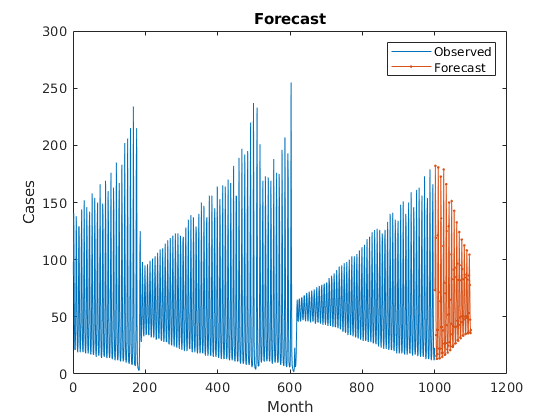

figure
plot(data_train)
hold on
idx = num_timesteps_train+1:(num_timesteps_train+num_timesteps_test);
plot(idx, y_pred,'.-');
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])